% Load the point of the stereo image (Mire)
P1M_1 = load ('Mire/Mire1.points');
P2M_2 = load ('Mire/Mire2.points');

% Load the poit of the stereo image (Rubik)
P1R_1 = load ('Rubik/Rubik1.points');
P2R_2 = load ('Rubik/Rubik2.points');

% Loading for Rubick's image
imgM1 = imread('Mire/Mire1.pgm');

[imgM1] = imConversion(imgM1);
imgM2 = imread('Mire/Mire2.pgm');

[imgM2] = imConversion(imgM2);
imgR1 = imread ('Rubik/Rubik1.pgm');
[imgR1] = imConversion(imgR1);
imgR2 = imread ('Rubik/Rubik2.pgm');
[imgR2] = imConversion(imgR2);

row_numberM = size(P1M_1, 1);
ones_columnM = ones(row_numberM, 1);

% convert in homogeneous cordinate
PM1 = [P1M_1, ones_columnM];
PM1 = PM1';
% want to consider a row vector

PM2 = [P2M_2, ones_columnM];
PM2 = PM2';

row_numberR = size(P1R_1, 1);
ones_columnR = ones(row_numberR, 1);

% convert in homogeneous cordinate
PR1 = [P1R_1, ones_columnR];
PR1 = PR1';
% want to consider a row vector

PR2 = [P2R_2, ones_columnR];
PR2 = PR2';

% Call the function for calculate the normalized fondamental matrix 
FM = EightPointsAlgorithm(PM1', PM2,row_numberM);
FM_N = EightPointsAlgorithmN(PM1, PM2); % Pass P1 transpose for the produìct inside the function 

FR = EightPointsAlgorithm(PR1', PR2,row_numberR);
FR_N = EightPointsAlgorithmN(PR1, PR2);
% evaluate the results of f:
% chceck the epipolar constraints x'Fx = 0,  check for every point
for i = 1:1:row_numberM
    % evaluate the epipolar constraint for not normalized point 
    result(i) = PM2(:,i)' * FM * PM1(:,i);
    % evaluate the epipolar constraint for not normalized point
    result_N(i) = PM2(:,i)' * FM_N * PM1(:,i);
end
disp("The ranks of FM and FM_N are");

The ranks of FM and FM_N are


rangoFM = rank(FM)

rangoFM = 2

rangoFM_N = rank(FM_N) % check on the rank = 2

rangoFM_N = 2


for i = 1:1:row_numberR
    % evaluate the epipolar constraint for not normalized point 
    result(i) = PR2(:,i)' * FR * PR1(:,i);
    % evaluate the epipolar constraint for not normalized point
    result_N(i) = PR2(:,i)' * FR_N * PR1(:,i);
end
disp("The ranks of FR and FR_N are");

The ranks of FR and FR_N are


rangoFR = rank (FR)

rangoFR = 2

rangoFR_N = rank(FR_N)  % check on the rank = 2

rangoFR_N = 2

Picture of not normalized

disp("Epipolar lines of FM");

Epipolar lines of FM


visualizeEpipolarLines(imgM1, imgM2, FM, P1M_1, P2M_2);
disp("Epipolar lines of FR");

Epipolar lines of FR


visualizeEpipolarLines(imgR1, imgR2, FR, P1R_1, P2R_2);

Picture of normalized

disp("Epipolar lines of FMN");

Epipolar lines of FMN


visualizeEpipolarLines( imgM1, imgM2, FM_N, P1M_1, P2M_2);
disp("Epipolar lines of FRN");

Epipolar lines of FRN


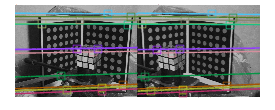

visualizeEpipolarLines( imgR1, imgR2, FR_N, P1R_1, P2R_2);

Epipole figure

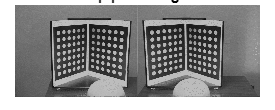

%needs to applicate the decomposition svd to F matrix F = UWV' and select
%the last columns of U and V
[U W V] = svd (FM_N);
last_col_U = U(1:2,end); % epipole left image
last_col_V = V(1:2,end); % epipole right image
figure;
Im = [imgM1 imgM2];
imshow(Im);
hold on
plot(last_col_U(1),last_col_U(2),'r*','Color', 'red','LineWidth', 8);
xv = [1:size(imgM1,2)];
plot(xv + last_col_V(1),last_col_V(2),'s', 'Color', [1,0,0], 'LineWidth', 8);
hold off
title ("Epipole image");

Part 2

Find and show Matches for Rubick

listR_ncc = findMatches(imgR1, imgR2, 'NCC');
listR_sift = findMatches(imgR1, imgR2, 'SIFT');

%disp("Show Matches of ListR_ncc");
%show_matches(imgR1, imgR2, listR_ncc, 0, 10);
disp("Show Matches of ListR_sift");

Show Matches of ListR_sift


show_matches(imgR1, imgR2, listR_sift, 1, 11);

Features matched: 606


Find and show matches for Mire

listM_ncc = findMatches(imgM1, imgM2, 'NCC');
listM_sift = findMatches(imgM1, imgM2, 'SIFT');
%disp("Show Matches of ListM_ncc");
%show_matches(imgM1, imgM2, listM_ncc, 0, 10);
disp("Show Matches of ListM_sift");

Show Matches of ListM_sift


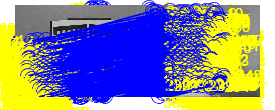

Features matched: 294


show_matches(imgM1, imgM2, listM_sift, 1, 11), title("show matches");


% Find the correspondence point extimated with image matching

Ransac for Mire

%disp("Epipolar with  bestF listMncc");
%[bestFMN, consensusMN, outliersMN] = ransacShow(imgM1,imgM2,listM_ncc, 0.008);
disp("Epipolar with  bestF listMsift");

Epipolar with  bestF listMsift


[bestFMS, consensusMS, outliersMS] = ransacShow (imgM1,imgM2,listM_sift,0.008);
for i = 1:1:size(consensusMS,2)
    % evaluate the epipolar constraint for not normalized point 
    result_FMS(i) = consensusMS(1:3, i)' * bestFMS * consensusMS(4:6, i);   
end

Ransac for Rubick

%disp("Epipolar with  bestF listRncc");
% [bestFRN, consensusRN, outliersRN] = ransacShow(imgR1,imgR2,listR_ncc, 0.008);
disp("Epipolar with  bestF listRsift");

Epipolar with  bestF listRsift


[bestFRS, consensusRS, outliersRS] = ransacShow(imgR1,imgR2,listR_sift, 0.008);
for i = 1:1:size(consensusRS,2)
    % evaluate the epipolar constraint for not normalized point 
    result_FRS(i) = consensusRS(1:3, i)' * bestFRS * consensusRS(4:6, i);   
end

Matlab built in function

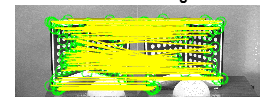

matchesM = findMatchesMat(imgM1, imgM2);

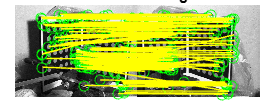

matchesR = findMatchesMat(imgR1, imgR2);

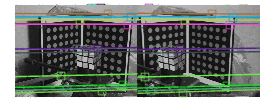


matchedPointsM1 = matchesM.matchedPoints1;
matchedPointsM2 = matchesM.matchedPoints2;

[fMMatrix, inliersMIdx] = estimateFundamentalMatrix(matchedPointsM1, matchedPointsM2, 'Method', 'RANSAC', 'NumTrials', 1000);
visualizeEpipolarLines(imgM1, imgM2, fMMatrix, P1M_1, P2M_2);

matchedPointsR1 = matchesR.matchedPoints1;
matchedPointsR2 = matchesR.matchedPoints2;

[fRMatrix, inliersRIdx] = estimateFundamentalMatrix(matchedPointsR1, matchedPointsR2, 'Method', 'RANSAC', 'NumTrials', 1000);
visualizeEpipolarLines(imgR1, imgR2, fRMatrix, P1R_1, P2R_2);